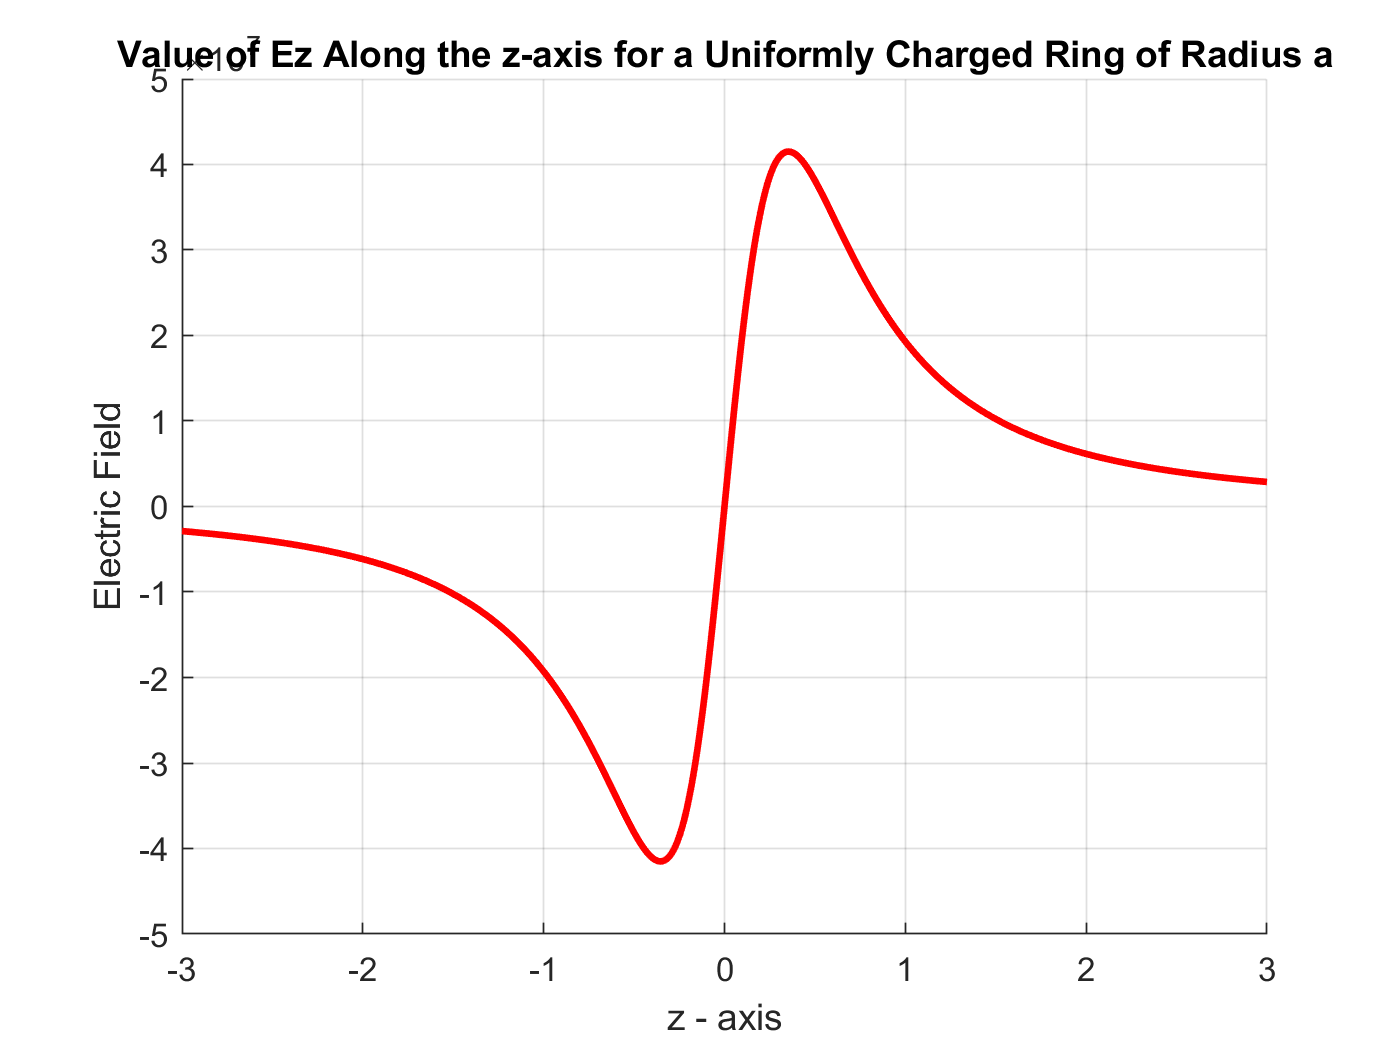

% Author: Shi Jie (Barney) Wei
% Date: 03/11/19

% 1) ringofcharge
a = 0.01;
rhol = -1e-9;
x = 0;
y = 0;
z = 0;
N = 500;

[Etot, Ex, Ey, Ez] = ringofcharge(a,rhol,x,y,z,N);

% 2. plotlineofcharge
%    2.1) Electric Field (Ez) Along the z-axis
plotlineofcharge11(0.5,3e-3/(2*pi*0.5),500);

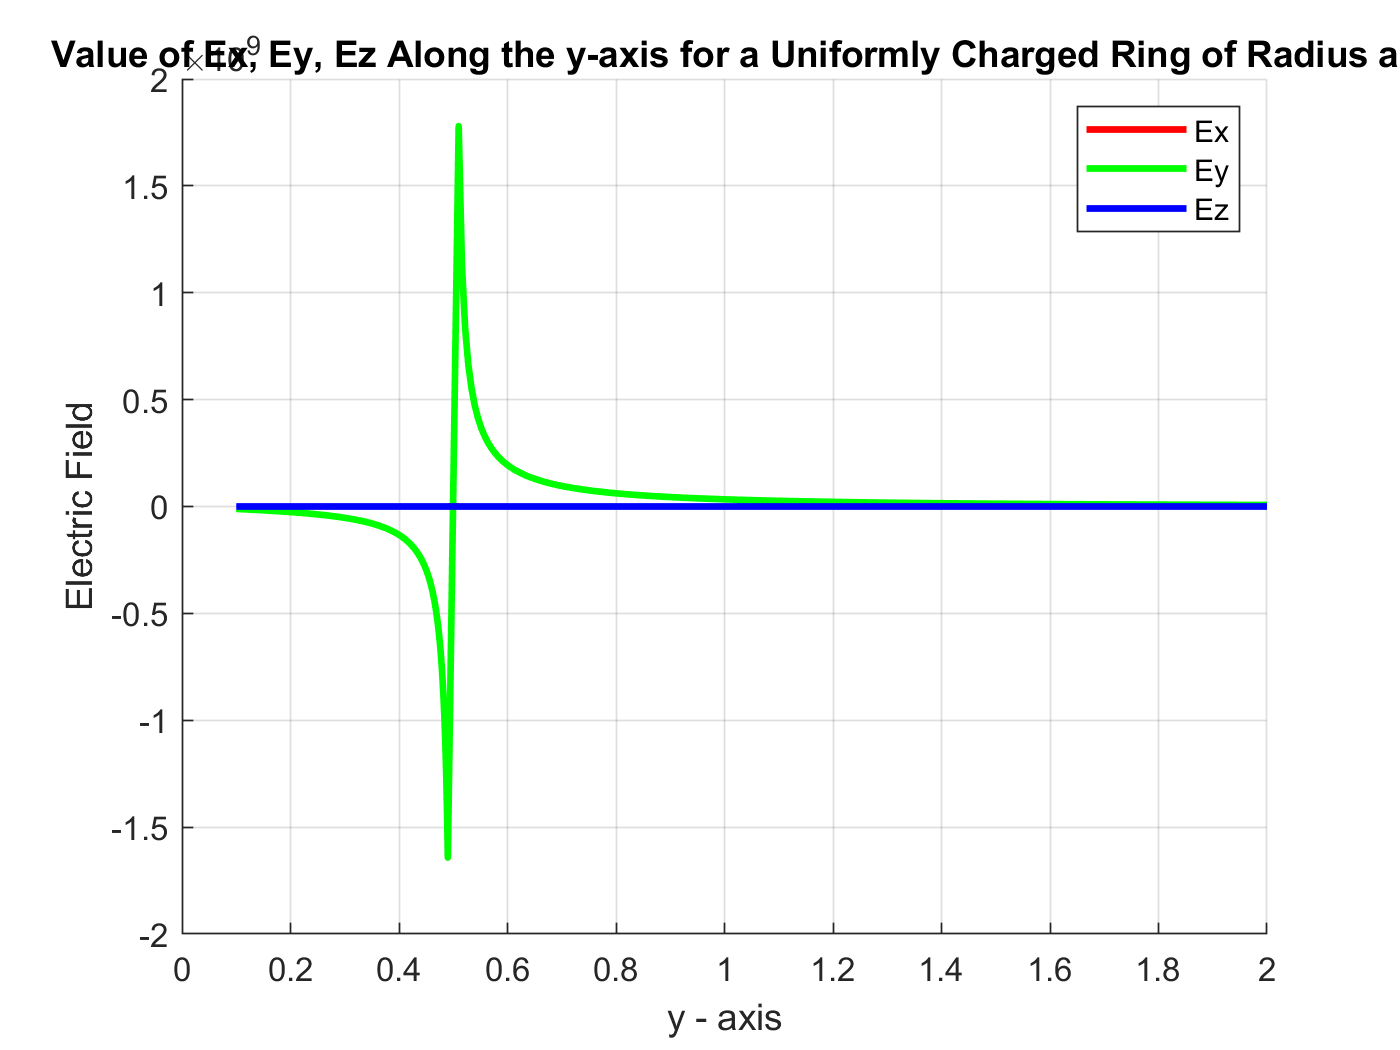

%    2.2) Electric Field (Ex, Ey, Ez) Along the y–axis
plotlineofcharge12(0.5,3e-3/(2*pi*0.5),500);

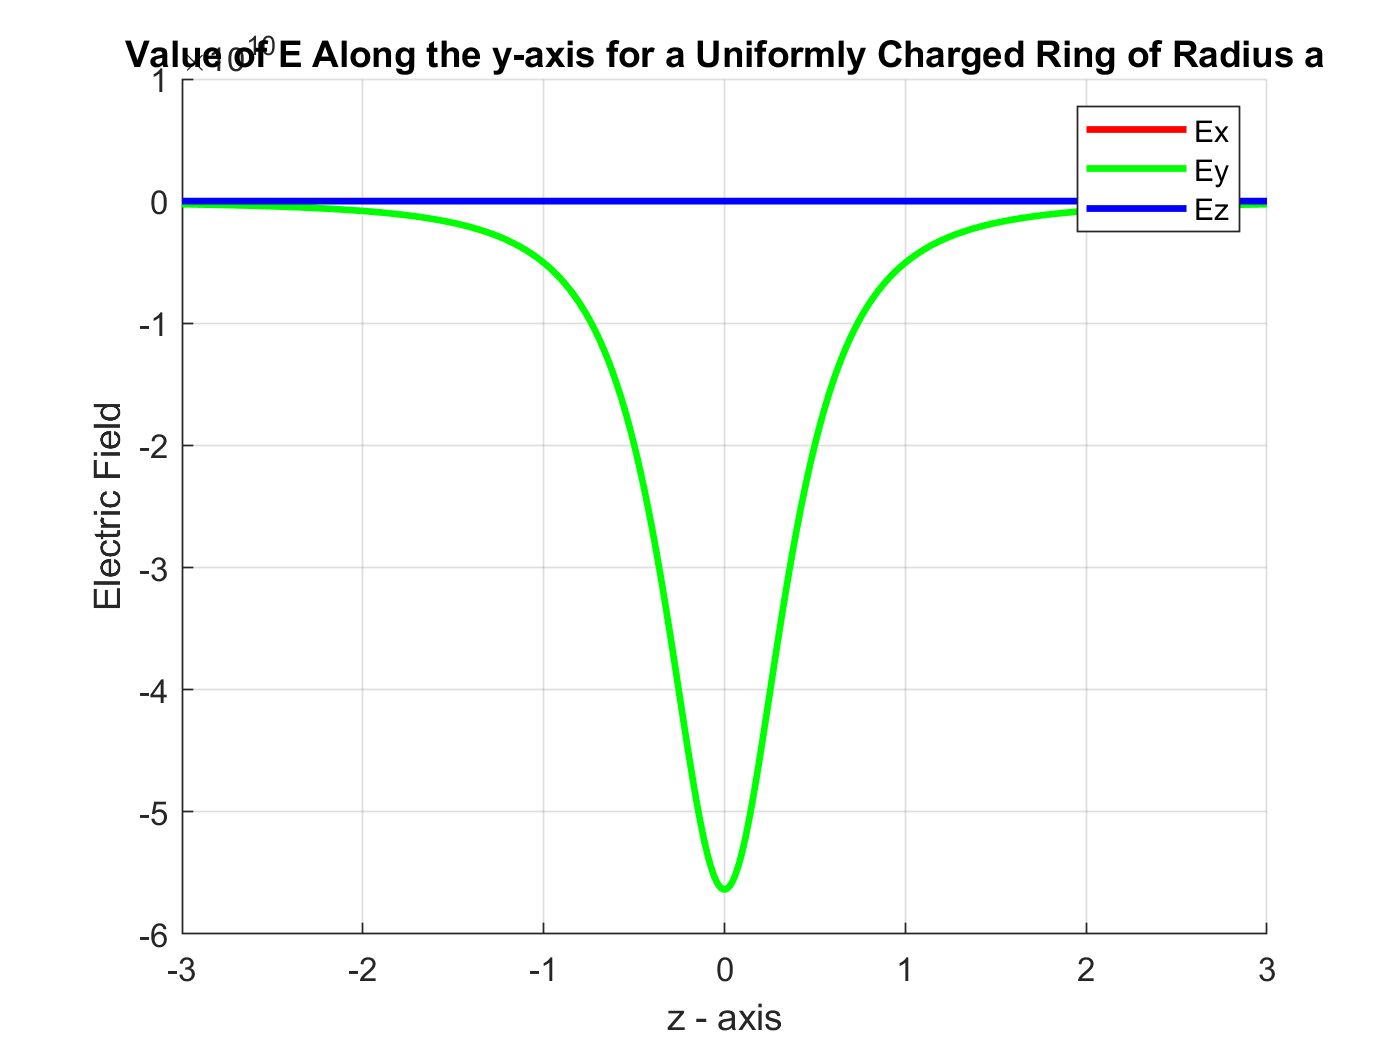

%    2.3) Non-Uniform Electric Fields Along the z–axis
N = 500;
rho_non_uniform = sin(linspace(0, 2*pi, N));
plotlineofcharge21(0.5,rho_non_uniform,N);

% A. ringofcharge

function [Etot,Ex,Ey,Ez]=ringofcharge(a,rhol,x,y,z,N)
    epsilon=8.854e-12;
    % Discretize x- and y-coordinates of 2a into N pieces
    dtheta = 2*pi/N;
    % The linspace command creates a vector that ranges from -a to a and has N elements with equal spacing
    theta_prime = linspace(0,2*pi,N);
    
    % Use a vectorized approach to "walk" along the line
    integrand=dtheta./(((x-a.*cos(theta_prime)).^2 + (y-a.*sin(theta_prime)).^2 + z^2).^(3/2));
    dEx=(x-a.*cos(theta_prime)).*integrand;
    dEy=(y-a.*sin(theta_prime)).*integrand;
    dEz=z.*integrand;
    
    % Do the "integration" by summing up the differential pieces that result from
    % each value of zprime.
    round_num = 6;
    Ex=round(((rhol*a)/(4*pi*epsilon)) * sum(dEx), round_num);
    Ey=round(((rhol*a)/(4*pi*epsilon)) * sum(dEy), round_num);
    Ez=round(((rhol*a)/(4*pi*epsilon)) * sum(dEz), round_num);
    Etot=(Ex^2+Ey^2+Ez^2)^0.5;
end
    
% B. ringofcharge_nonuniformcharge
function [Etot,Ex,Ey,Ez]=ringofcharge_nonuniform(a,rhol,x,y,z,N)
    epsilon=8.854e-12;
    % Discretize x- and y-coordinates of 2a into N pieces
    dtheta = 2*pi/N;
    % The linspace command creates a vector that ranges from -a to a and has N elements with equal spacing
    theta_prime = linspace(0,2*pi,N);
    
    % Use a vectorized approach to "walk" along the line
    integrand=dtheta./(((x-a.*cos(theta_prime)).^2 + (y-a.*sin(theta_prime)).^2 + z^2).^(3/2));
    dEx=(x-a.*cos(theta_prime)).*integrand;
    dEy=(y-a.*sin(theta_prime)).*integrand;
    dEz=z.*integrand;
    
    % Do the "integration" by summing up the differential pieces that result from
    % each value of zprime.
    round_num = 6;
    Ex=round(sum(((rhol.*a)./(4*pi*epsilon)) .* dEx), round_num);
    Ey=round(sum(((rhol.*a)./(4*pi*epsilon)) .* dEy), round_num);
    Ez=round(sum(((rhol.*a)./(4*pi*epsilon)) .* dEz), round_num);
    Etot=(Ex^2+Ey^2+Ez^2)^0.5;
end

% C. plotlineofcharge11
function plotlineofcharge11(a,rhol,N)
    z=linspace(-3,3,N); % points at which we want to find the fields.
    epsilon=8.854e-12;
    % 1) Calculate electric field
    Eztheory = (rhol*a.*z) ./ (2*epsilon*(z.^2+a^2).^(3/2));
    for i=1:length(z)
        [~, ~, ~, Ez] = ringofcharge(a,rhol,0,0,z(i),N);
        Ez_val(i) = Ez;
    end
    % 2) Plot
    figure
    hold on;
    plot(z, Eztheory, 'b-', 'Linewidth', 2);
    plot(z, Ez_val, 'r-', 'Linewidth', 2);
    xlabel('z - axis');
    ylabel('Electric Field');
    title('Value of Ez Along the z-axis for a Uniformly Charged Ring of Radius a');
    grid on;
end

% D. plotlineofcharge12
function plotlineofcharge12(a,rhol, N)
    y1=linspace(0.1,0.49,N/2); % points at which we want to find the fields.
    y2=linspace(0.51,2,N/2);
    y = [y1 y2];
    % 1) Calculate electric field
    for i=1:length(y)
        [~, Ex, Ey, Ez] = ringofcharge(a,rhol,0,y(i),0,N);
        Ex_val(i) = Ex;
        Ey_val(i) = Ey;
        Ez_val(i) = Ez;
    end
    % 2) Plot
    figure
    hold on;
    plot(y, Ex_val, 'r-', 'Linewidth', 2);
    plot(y, Ey_val, 'g-', 'Linewidth', 2);
    plot(y, Ez_val, 'b-', 'Linewidth', 2);
    xlabel('y - axis');
    ylabel('Electric Field');
    title('Value of Ex, Ey, Ez Along the y-axis for a Uniformly Charged Ring of Radius a');
    legend('Ex', 'Ey', 'Ez');
    grid on;
end

% E. plotlineofcharge21
function plotlineofcharge21(a,rhol, N)
    z=linspace(-3,3,N); % points at which we want to find the fields.
    % 1) Calculate electric field
    for i=1:length(z)
        [~, Ex, Ey, Ez] = ringofcharge_nonuniform(a,rhol,0,0,z(i),N);
        Ex_val(i) = Ex;
        Ey_val(i) = Ey;
        Ez_val(i) = Ez;
    end
    % 2) Plot
    figure
    hold on;
    plot(z, Ex_val, 'r-', 'Linewidth', 2);
    plot(z, Ey_val, 'g-', 'Linewidth', 2);
    plot(z, Ez_val, 'b-', 'Linewidth', 2);
    xlabel('z - axis');
    ylabel('Electric Field');
    title('Value of E Along the y-axis for a Uniformly Charged Ring of Radius a');
    legend('Ex','Ey', 'Ez');
    grid on;
end